## Recap

1/$K_{ij}$ = $\int_{0}^{L}\frac{dN_j}{dx} AE \frac{dN_i}{dx}~dx$

 2/$f_j$  = $\int_0^LN_j{q}~dx + \left. N_j{R}\right|_{x=L}~$ 

3/ solve

Now let's replace symbolic variable with discretized value for using MATLAB

clear all; close all;
%
%Pre - fem 
%mesh
%Material and Length
%
 A = 1.0;
 L = 1.0;
 E = 1.0;
 a = 1.0;
 R = 1.0;
 %note that is it not really physics based analysis all this ones...

 %number of elements
 e = 3;
 %discretization step h
 h = L/e;
 %number of node = number of element + 1
 n = e+1;

 %numbering node
 %node 1 start at 0, node n at (n-1)*h
 for i=1:n
  node(i) = (i-1)*h;
 end

 %numbering element & connectivity
 %element 1 connectivity : [1 2] ... element e [e e+1] 
 %means [n-1 n]
 for i=1:e
  elem(i,:) = [i i+1];
 end

%
%Assembly
%
%initialize with 0 matrix
 K = zeros(n);
 f = zeros(n,1);
 
%loop on element form 1 to e
 for i=1:e
    node1 = elem(i,1);
  node2 = elem(i,2);
  %compute once K and f
  Ke = elementStiffness(A, E, h);
  fe = elementLoad(node(node1),node(node2), a, h);
  %assembly
  K(node1:node2,node1:node2) = K(node1:node2,node1:node2) + Ke;
  f(node1:node2) = f(node1:node2) + fe;
 end


% %BCs &Loads

  f(n) = f(n) + 1.0;

  Kred = K(2:n,2:n);
  fred = f(2:n);


% Solver

 
  d = inv(Kred)*fred;
%  %d=Kred\fred
 
  dsol = [0 d'];
 
 fsol = K*dsol';
 sum(fsol)

ans = -4.4409e-16

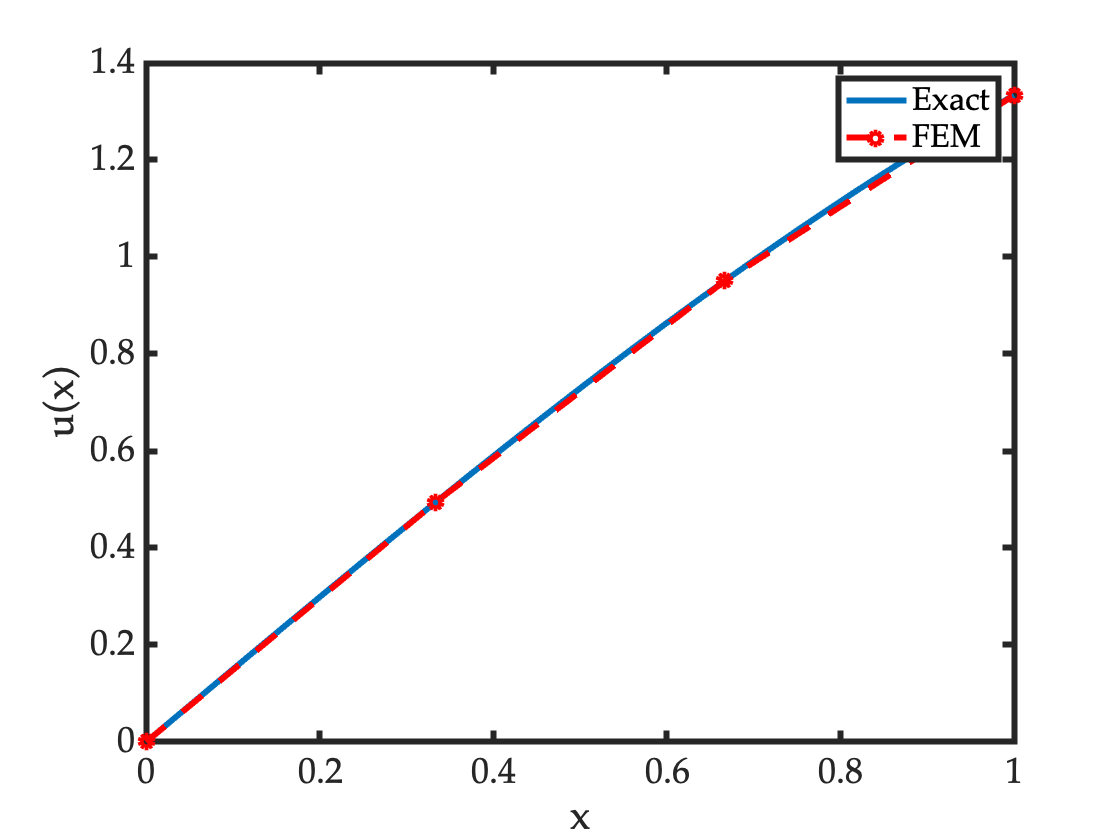

 figure;
 p0 = plotDisp(E, A, L, R, a);
 p1 = plot(node, dsol, 'ro--', 'LineWidth', 3); hold on;
 legend([p0 p1],'Exact','FEM');

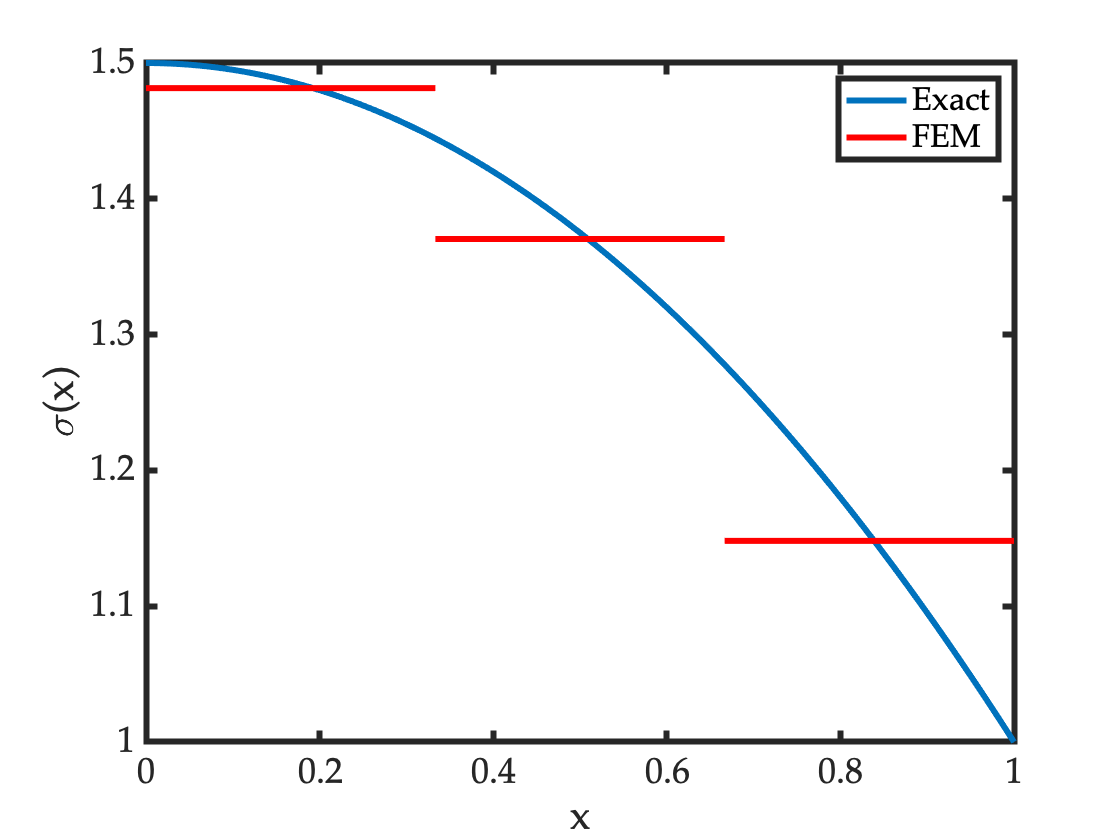

 
 for i=1:e
  node1 = elem(i,1);
  node2 = elem(i,2);
  u1 = dsol(node1);
  u2 = dsol(node2);
  [eps(i), sig(i)] = elementStrainStress(u1, u2, E, h);
 end

 figure;
 p0 = plotStress(E, A, L, R, a);
 for i=1:e
  node1 = node(elem(i,1));
  node2 = node(elem(i,2));
  p1 = plot([node1 node2], [sig(i) sig(i)], 'r-','LineWidth',3); hold on;
 end
 legend([p0 p1],'Exact','FEM');

That's all